function estimate = markovpi(Ntrials,d)
Nhits=0;
cords=[1,1];

for i = 1:Ntrials
    dx=d*(2*rand()-1); %dx = ran(-delta,delta)
    dy=d*(2*rand()-1); %dy = ran(-delta,delta)
    %checking if lands in helipad sqaure
    if abs(cords(1)+dx)<1
        if abs(cords(2)+dy)<1
            cords(1) = cords(1) + dx;
            cords(2) = cords(2) + dy;
        end
    end
    %checking if lands in helipad circle
    if cords(1)^2 + cords(2)^2 < 1
        Nhits=Nhits+1;
    end
end
estimate = Nhits/Ntrials; %estimate of pi/4
end

markovpi(1000,0.2)

ans = 0.8460

markovpi(10000,0.2)

ans = 0.7660

markovpi(100000,0.2)

ans = 0.7862

markovpi(1000000,0.2)

ans = 0.7844

deltas=linspace(0.01,10,1000);
N=100; %100 estimates for each delta


estimates=zeros(1,N);
sd=zeros(1,length(deltas));

for i = 1:length(deltas)
    for j = 1:N
        estimates(j)=4*markovpi(10000,deltas(i))/10000; 
    end
    sd(i) = std(estimates); 
    %sd(x-c)=sd(x) for c constant hence no need to actually include 3.1415
end

%From graph we can see for delta very small we get high standard deviation,
%likely due to the fact we are not travesing the entire helipad with the
%amount of trials we have proposed. For delta approximatly between 0.5 and
%1.5 we get the lowest standard deviation hence the greatest precision in
%estimating pi. As delta increases beyond these values the standard
%deviation increases, due to the fact the higher we increase delta the more
%likely the stones will land outside the helipad.

plot(deltas,sd)
xlabel('Delta (Throwing Range)')
ylabel('Standard deviation of "pi estimate - 3.1415"')
title('Precison via standard deviation (Joseph Dearing)')

function estimate = metropolishastings(Ntrials,d)
Nhits = 0;
cords = [1,1];
h = sqrt(3)/2*d; %height of triangle

for i = 1:Ntrials
    
    %producing valid throw in triangle
    %i.e. sampling x'
    intri = false;
    while ~intri
        dx=d*(rand()-0.5);
        dy=d*(rand()-0.5);
        xtri = [cords(1),cords(1)+d/2,cords(1)-d/2];
        ytri = [cords(2)+h/2,cords(2)-h/2,cords(2)-h/2];
        if inpolygon(cords(1) + dx, cords(2) + dy, xtri, ytri)
            xprime=cords(1)+dx;
            yprime=cords(2)+dy;
            intri = true;
        end        
    end

    %checking if in square and if reverse is possible
    if abs(xprime)<1
        if abs(yprime)<1
            xtriprime = [xprime,xprime+d/2,xprime-d/2];
            ytriprime = [yprime+h/2,yprime-h/2,yprime-h/2];
            if inpolygon(cords(1), cords(2), xtriprime, ytriprime)
                %if true A(x',x)=1/(area of equalateral triangle with side lengths delta)
                %Since A(x,x')=1/(area of equalateral triangle with side lengths delta)
                %and π(x) = π(x') as we have uniform distribution, the
                %Metropolis-Hastings filter is one, hence the move is
                %accepted
                %if false A(x',x)=0
                %therefore the Metroplois-Hastings filter is zero, hence
                %move is rejected.
                cords(1)=xprime;
                cords(2)=yprime;
            end
        end
    end

    if cords(1)^2 + cords(2)^2 < 1
        Nhits=Nhits+1;
    end
end

estimate = Nhits/Ntrials; %estimate of pi/4
end

metropolishastings(1000,0.2)
metropolishastings(10000,0.2)
metropolishastings(100000,0.2)
metropolishastings(1000000,0.2)

function metropolis(d,t)

x=0; 
samples=zeros(1,t);

pi24=@(x)exp(-x^2/2-x^4/2);

for i = 1:t

    dx=d*(2*rand()-1);
    r=pi24(x+dx)/pi24(x);
    upsilon=rand();

    if upsilon<min(1,r)
        x=x+dx;
    end

    samples(i)=x;

end

xvec=linspace(min(samples),max(samples),1000);
y24=exp(-(xvec.^2)/2 -(xvec.^4)/2);
area=trapz(xvec,y24);
y24norm=y24/area;

%From graph we can see that the Metropolis algorithm samples the Boltzmann
%distribution of the anharmonic oscialltor without any approximation. For
%sufficiently large t and a suitable delta. In testing of code it seems we
%need t to be at least 6 orders of magnitude greater than delta to get a
%plot from which we can give the above conclusion.
clf;
hold on 
plot(xvec, y24norm, 'r-', 'LineWidth', 2)
histogram(samples,50,'Normalization','pdf')
xlabel('Position x')
ylabel('Probability Density')
p={['delta=',num2str(d)],['timesteps=',num2str(t)]};
annotation('textbox',[0.15 0.8 0.1 0.1],'string',p)
title('Metropolis Sampling of Anharmonic Oscillator (Joseph Dearing)')
legend('Boltzman Distribution','Metropolis Samples')
hold off
end

metropolis(0.3,100000)

function factormetro(d,t)
x=0; 
samples=zeros(1,t);
pi2=@(x)exp(-(x^2)/2);
pi4=@(x)exp(-(x^4)/4);
for i = 1:t
    dx=d*(2*rand()-1);
    r2=pi2(x+dx)/pi2(x);
    r4=pi4(x+dx)/pi4(x);
    upsilon=rand();
    if upsilon<(min(1,r2)*min(1,r4))
        x=x+dx;
    end
    samples(i)=x;
end

xvec=linspace(min(samples),max(samples),1000);
y24=exp(-(xvec.^2)/2 -(xvec.^4)/4);
area=trapz(xvec,y24);
y24norm=y24/area;

%As before we can see that the algorithm samples the Boltzmann distribution 
%of the anharmonic oscialltor without any approximation. Futhermore, it
%from testing it seems we need the same difference in order of magnitude of
%delta and t to make such conclusion.

%pi24(x)=pi2(x)*pi4(x)
%Meaning the Factor-Metropolis algorithm preserves the same detailed
%balance condition as that for the Metropolis algorithm, hence it converges
%to the Boltzmann distribution of the anharmonic oscillator without any
%approximation.
clf;
hold on 
plot(xvec, y24norm, 'r-', 'LineWidth', 2)
histogram(samples,50,'Normalization','pdf')
xlabel('Position x')
ylabel('Probability Density')
p={['delta=',num2str(d)],['timesteps=',num2str(t)]};
annotation('textbox',[0.15 0.8 0.1 0.1],'string',p)
title('Factor-Metropolis Sampling of Anharmonic Oscillator (Joseph Dearing)')
legend('Boltzman Distribution','Factor-Metropolis Samples')
hold off
end
factormetro(0.3,1000000)

function liftedmetropolis(d,t)

x=0;
samples=zeros(1,t);

sigma=1;
pi24=@(x)exp(-x^2/2-x^4/4);

for i = 1:t
    dx=d*(2*rand()-1);
    upsilon=rand();

    if upsilon < min(1,pi24(x+sigma*dx)/pi24(x))
        x=x+sigma*dx;
    else
        sigma=-sigma;
    end

    samples(i)=x;

end


xvec=linspace(min(samples),max(samples),1000);
y24=exp(-(xvec.^2)/2 -(xvec.^4)/4);
area=trapz(xvec,y24);
y24norm=y24/area;

clf;
hold on 
plot(xvec, y24norm, 'r-', 'LineWidth', 2)
histogram(samples,50,'Normalization','pdf')
xlabel('Position x')
ylabel('Probability Density')
p={['delta=',num2str(d)],['timesteps=',num2str(t)]};
annotation('textbox',[0.15 0.8 0.1 0.1],'string',p)
title('Lifted-Metropolis Sampling of Anharmonic Oscillator (Joseph Dearing)')
legend('Boltzman Distribution','Lifted-Metropolis Samples')
hold off
end

liftedmetropolis(0.1,10000000)

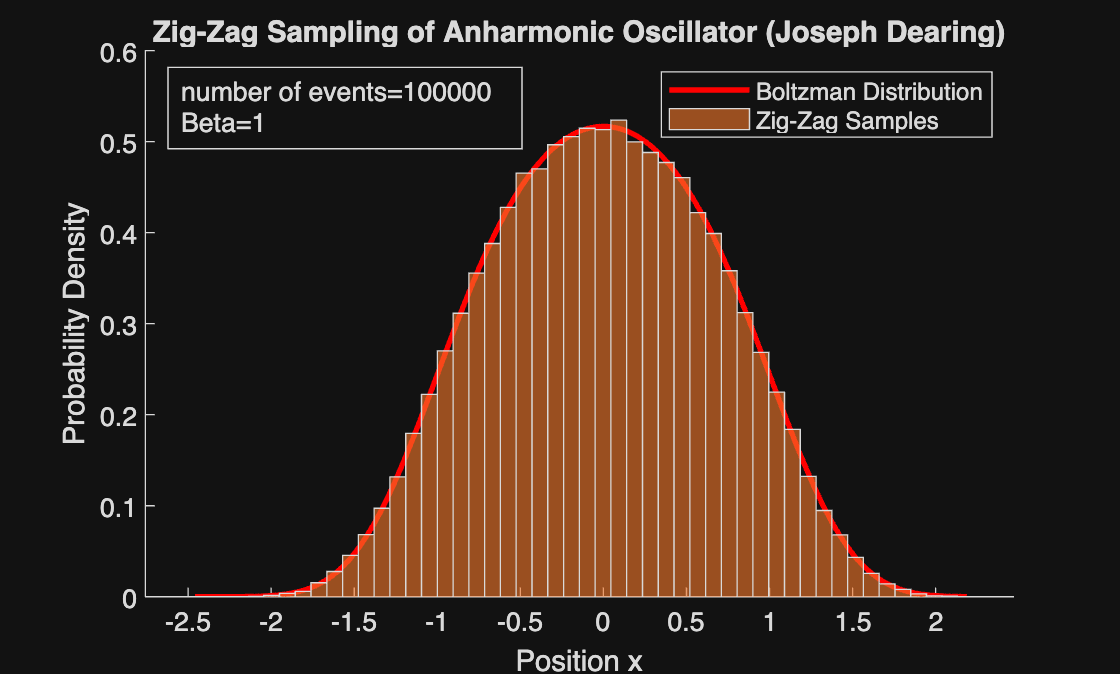

%Joseph Dearing

function zigzag(n,b) %(number of events,beta)

x=0;
t=0;
sigma=1;
samples=[];

for i = 1:n 
    xev=sigma*sqrt(-1+sqrt(1-4*(b^-1)*log(rand())));
    tev=t+abs(xev-x);
    
    tstar=floor(t)+1:floor(tev);

    if ~isempty(tstar)
        newsamples=x+sigma*(tstar-t);
        samples=[samples,newsamples];
    end

    x=xev;
    sigma=-sigma;
    t=tev;
    

end

xvec=linspace(min(samples),max(samples),1000);
y24=exp(-(xvec.^2)/2 -(xvec.^4)/4);
area=trapz(xvec,y24);
y24norm=y24/area;

%From the graph we can clearly see that the metropolis, lifted-metropolis
%and the event driven zig-zag algorithms sample the same distribution
%correctly


%detailed balance equation pi(x)P(x,x')=pi(x')P(x',x) for all x,x'
%global balance pi(x)=sum over x'[pi(x')P(x',x)]
%Metropolis satifies detailed since its a reversible markov chain
%Lifted and Zig-Zag satisfy global since they are non-reversible

clf;
hold on 
plot(xvec, y24norm, 'r-', 'LineWidth', 2)
histogram(samples,50,'Normalization','pdf')
xlabel('Position x')
ylabel('Probability Density')
p={['number of events=',num2str(n)],['Beta=',num2str(b)]};
annotation('textbox',[0.15 0.8 0.1 0.1],'string',p)
title('Zig-Zag Sampling of Anharmonic Oscillator (Joseph Dearing)')
legend('Boltzman Distribution','Zig-Zag Samples')
hold off
end

zigzag(100000,1)